filename = 'CueRewardSize-SPE-03-24-2020';
load([filename,'_D.mat']);

Calculate lick probability by condition(i.e. reward size)

align by cue on time and go for .5 second before and 3 seconds after

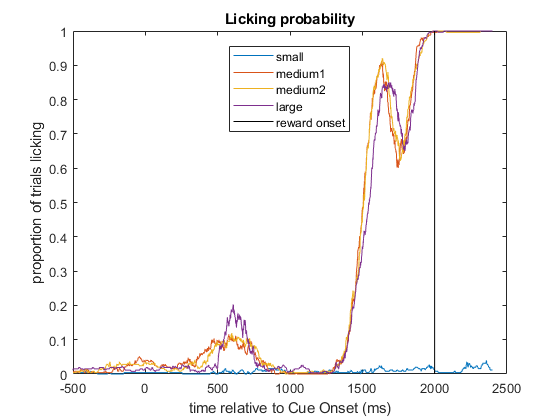

T = 3501;
lickProbability = zeros(4,T); % first count by condition/cue identity
trialCount = zeros(4,1);

for trind = 1:length(D.TrialNumber)
    if ~D.Rewarded(trind) % rewarded/successful trials only
        continue;
    end
    if strcmp(D.CueName{trind},'stimA') 
        cond = 1;
    elseif strcmp(D.CueName{trind},'stimB1') 
        cond = 2;
    elseif strcmp(D.CueName{trind},'stimB2') 
        cond = 3;
    else
        cond = 4;
    end
    trialCount(cond) = trialCount(cond) + 1;
    cueOn = D.CueOnTime(trind);
    lickingBinary = D.LickingBinary{trind};
    lickProbability(cond,:) = lickProbability(cond,:) ...
        + double(lickingBinary((cueOn-500):(cueOn+3000)))';
end

for cind = 1:4
    lickProbability(cind,:) = lickProbability(cind,:) ...
        / trialCount(cind);
end

figure;
for cind = 1:4
    plot(-500:3000,lickProbability(cind,:)); hold on;
end
xlabel('time relative to Cue Onset (ms)');
ylabel('proportion of trials licking')
line([2000,2000],[0,1],'color','k');
legend({'small','medium1','medium2','large','reward onset'},'location','best');
title('Licking probability')